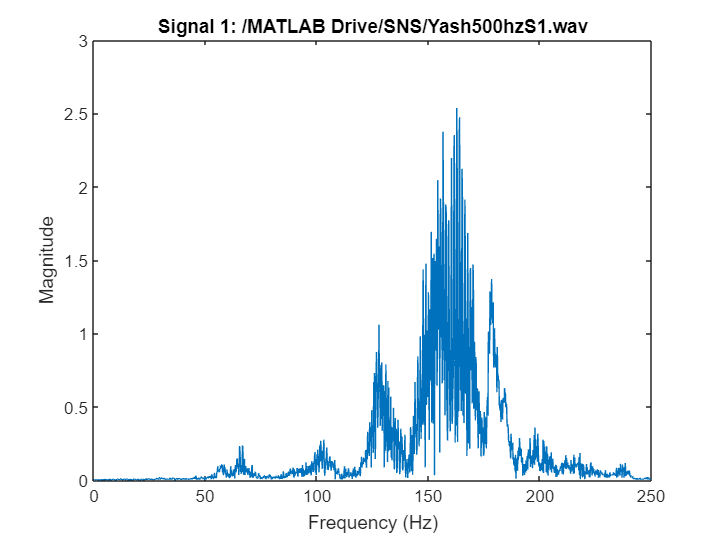

num_inp = 1; % we can take any input from the user in form of positive  integers and We take it as 1
filenames = cell(1, num_inp); %cell arrays are created to hold filenames, audio and sample rate
audio_data = cell(1, num_inp);
fs_all = zeros(1, num_inp);

for i = 1:num_inp % for loop is used to run the code for each input
   prompt = sprintf('Enter the name of WAV file %d: ', i);
   filenames{i} = input(prompt, 's');
   [audio_data{i}, fs_all(i)] = audioread(filenames{i});% we use audioread library which read our voice signals and sample rates in form of wave signal
   % which are stored in the corresponding indices of the audio_data and fs_all arrays
   N = length(audio_data{i});% length of audio_data is created
  
   freqs = (0:N-1)*(fs_all(i)/N);% frequency axis is created
   %which generates a vector of frequencies ranging from 0 Hz to the Nyquist frequency (half the sample rate), with a frequency resolution of fs_all(i)/N Hz
   freqs = freqs(1:ceil(N/2)); % only keep the positive half of the spectrum
  
   X = zeros(1, N);
   for k = 1:N %Nested loop are used to find the discrete fourier transform of audio_data
       for n = 1:N
           X(k) = X(k) + audio_data{i}(n)*exp(-2*pi*1i*(k-1)*(n-1)/N);
           % the loop run through each frequency 
           % which calculate the complex amplitude of that frequency using
           % above formula where n iterates through each sample of audio
       end
   end
  
   mags = abs(X);
   mags = mags(1:ceil(N/2)); % only keep the positive half of the spectrum
  
   subplot(num_inp, 1, i);
   plot(freqs, mags);% The frequency axis (freqs) is plotted on the x-axis and the magnitude spectrum (mags) is plotted on the y-axis
   xlabel('Frequency (Hz)');
   ylabel('Magnitude');
   title(sprintf('Signal %d: %s', i, filenames{i}));
end